# --- AE484 Projesi: IMU + GPS Entegrasyonu (EKF) ---

clc; clear; close all;

% --- Sabitler ---
g = 9.80665; % Yerçekimi ivmesi (m/s^2)
R_EARTH = 6378137.0; % WGS84 Ekvator yarıçapı

logFilesPath = 'C:\Users\User\Desktop\METU\AE484\Proje\AGZ\Log Files';
fprintf('Veri yolu: %s\n', logFilesPath);

Veri yolu: C:\Users\User\Desktop\METU\AE484\Proje\AGZ\Log Files



try
    accel_data_raw = readtable(fullfile(logFilesPath, 'RawAccel.csv'));
    gyro_data_raw = readtable(fullfile(logFilesPath, 'RawGyro.csv'));
    gps_data_raw = readtable(fullfile(logFilesPath, 'OnboardGPS.csv'));
    onboard_pose_raw = readtable(fullfile(logFilesPath, 'OnboardPose.csv'));
catch ME
    error('CSV dosyaları bulunamadı veya okunamadı. Lütfen dosya yollarını kontrol edin: %s', ME.message);
end

% IMU Verileri 
% disp('RawAccel.csv sütun adları:'); disp(accel_data_raw.Properties.VariableNames);
time_accel = accel_data_raw.Timpstemp * 1e-06; % saniyeye böyle çevrilir sanırım
acc_b_input_ms2 = [accel_data_raw.x, accel_data_raw.y, accel_data_raw.z]; % m/s^2 olmalı

% disp('RawGyro.csv sütun adları:'); disp(gyro_data_raw.Properties.VariableNames);
time_gyro = gyro_data_raw.Timpstemp * 1e-06; % saniye
gyro_b_input_red_sec = [gyro_data_raw.x, gyro_data_raw.y, gyro_data_raw.z]; % rad/sec olmalı

% Ground Truth
% disp('OnboardPose.csv sütun adları:'); disp(onboard_pose_raw.Properties.VariableNames);
time_onboard_pose_gt = onboard_pose_raw.Timpstemp * 1e-06;
v_onboard_ned_gt_raw = [onboard_pose_raw.Vel_x, onboard_pose_raw.Vel_y, onboard_pose_raw.Vel_z]; % m/s
q_onboard_ned_gt_raw_matlab = [onboard_pose_raw.Attitude_w, onboard_pose_raw.Attitude_x, onboard_pose_raw.Attitude_y, onboard_pose_raw.Attitude_z];

% disp('OnboardGPS.csv sütun adları:'); disp(gps_data_raw.Properties.VariableNames);
time_gps_gt = gps_data_raw.Timpstemp * 1e-06;
lat_gps_gt = gps_data_raw.lat; % derece
lon_gps_gt = gps_data_raw.lon; % derece
alt_gps_gt = gps_data_raw.alt*1e-03;  % metre above MSL

% --- Zaman Senkronizasyonu ve Veri Interpole Etme ---
% fprintf('Zaman senkronizasyonu ve interpolasyon...\n');
time_accel_norm = time_accel - time_accel(1);
time_gyro_norm = time_gyro - time_gyro(1);
time_gps_gt_norm = time_gps_gt - time_gps_gt(1);
time_onboard_pose_gt_norm = time_onboard_pose_gt - time_onboard_pose_gt(1);

% Tüm sensörlerin ortak zaman aralığı
t_start_common = max([time_accel_norm(1), time_gyro_norm(1), time_gps_gt_norm(1), time_onboard_pose_gt_norm(1)]);
t_end_common = min([time_accel_norm(end), time_gyro_norm(end), time_gps_gt_norm(end), time_onboard_pose_gt_norm(end)]);

% Referans zaman adımı (dt) 
if length(time_accel) > length(time_gyro)
    master_time_ref = time_accel_norm;
else
    master_time_ref = time_gyro_norm;
end
dt_master_calc = median(diff(master_time_ref));
if isnan(dt_master_calc) || dt_master_calc <= 1e-6; dt_master_calc = 1/200; end % 200 Hz

% Ortak zaman vektörü
master_time = (t_start_common : dt_master_calc : t_end_common)';
if isempty(master_time) || length(master_time) < 10 % En az 10 örnek olsun
    error('Ortak zaman vektörü oluşturulamadı veya çok kısa. Sensörlerin zaman damgalarını ve çakışmalarını kontrol edin.');
end
dt = median(diff(master_time));
% fprintf('Ortak zaman vektörü oluşturuldu (%.d adım, dt ~ %.4f s).\n', length(master_time), dt);

% Girdi IMU verilerini master_time'a interpole et
acc_b = interp1(time_accel_norm, acc_b_input_ms2, master_time, 'linear');
gyro_b = interp1(time_gyro_norm, gyro_b_input_red_sec, master_time, 'linear');

% Yer Gerçeği Hız ve Tutum verilerini master_time'a interpole et
v_gt_ned_interp = interp1(time_onboard_pose_gt_norm, v_onboard_ned_gt_raw, master_time, 'linear');
q_w_interp = interp1(time_onboard_pose_gt_norm, q_onboard_ned_gt_raw_matlab(:,1), master_time, 'linear');
q_x_interp = interp1(time_onboard_pose_gt_norm, q_onboard_ned_gt_raw_matlab(:,2), master_time, 'linear');
q_y_interp = interp1(time_onboard_pose_gt_norm, q_onboard_ned_gt_raw_matlab(:,3), master_time, 'linear');
q_z_interp = interp1(time_onboard_pose_gt_norm, q_onboard_ned_gt_raw_matlab(:,4), master_time, 'linear');
q_gt_matlab_interp = [q_w_interp q_x_interp q_y_interp q_z_interp];

% Yer Gerçeği Pozisyonu için GPS verisini master_time'a interpole et ('nearest' genellikle GPS için daha iyi)
lat_gps_gt_interp = interp1(time_gps_gt_norm, lat_gps_gt, master_time, 'nearest');
lon_gps_gt_interp = interp1(time_gps_gt_norm, lon_gps_gt, master_time, 'nearest');
alt_gps_gt_interp = interp1(time_gps_gt_norm, alt_gps_gt, master_time, 'nearest');

% Interpole edilmiş verilerde NaN kontrolü ve temizliği
valid_idx = ~any(isnan(acc_b),2) & ~any(isnan(gyro_b),2) & ...
            ~any(isnan(v_gt_ned_interp),2) & ~any(isnan(q_gt_matlab_interp),2) & ...
            ~isnan(lat_gps_gt_interp) & ~isnan(lon_gps_gt_interp) & ~isnan(alt_gps_gt_interp);

if sum(~valid_idx) > 0
    fprintf('Uyarı: Interpole edilmiş verilerden %d adet NaN içeren örnek kaldırıldı.\n', sum(~valid_idx));
end
master_time = master_time(valid_idx);
acc_b = acc_b(valid_idx,:);
gyro_b = gyro_b(valid_idx,:);
v_gt_ned = v_gt_ned_interp(valid_idx,:); % Yeniden adlandırma
q_gt_matlab = q_gt_matlab_interp(valid_idx,:); % Yeniden adlandırma
lat_gps_gt_interp = lat_gps_gt_interp(valid_idx);
lon_gps_gt_interp = lon_gps_gt_interp(valid_idx);
alt_gps_gt_interp = alt_gps_gt_interp(valid_idx);

num_samples = length(master_time);
if num_samples < 10
    error('Senkronizasyon ve NaN temizliği sonrası yeterli veri kalmadı.');
end
dt = median(diff(master_time)); % dt'yi yeniden hesapla

% Quaternion normalizasyonu (GT için)
for ii = 1:size(q_gt_matlab, 1) % Satır sayısı kadar dön
    norm_q = norm(q_gt_matlab(ii,:));
    if norm_q > 1e-6
        q_gt_matlab(ii,:) = q_gt_matlab(ii,:) / norm_q;
    else
        q_gt_matlab(ii,:) = [1 0 0 0]; % Geçersizse varsayılan ata
    end
end

% GPS LLH'dan lokal NED'e dönüşüm (Yer Gerçeği Pozisyonu ve EKF Ölçümü için)
lat0_rad_gt = lat_gps_gt_interp(1) * pi/180;
lon0_rad_gt = lon_gps_gt_interp(1) * pi/180;
alt0_gt = alt_gps_gt_interp(1);
p_gt_ned_from_gps = zeros(num_samples,3);
for k_gt = 1:num_samples
    p_gt_ned_from_gps(k_gt,:) = llh2ned_flat(lat_gps_gt_interp(k_gt), lon_gps_gt_interp(k_gt), alt_gps_gt_interp(k_gt), lat0_rad_gt, lon0_rad_gt, alt0_gt);
end
fprintf('Yer gerçeği pozisyonu (GPS''ten) NED çerçevesine dönüştürüldü.\n');

Yer gerçeği pozisyonu (GPS'ten) NED çerçevesine dönüştürüldü.


## --- Adım 3: Sadece IMU ile Navigasyon (Strapdown INS) ---


fprintf('Sadece IMU ile navigasyon (INS) başlıyor...\n');

Sadece IMU ile navigasyon (INS) başlıyor...


p_ins = zeros(num_samples,3);
v_ins = zeros(num_samples,3);
q_ins_matlab = zeros(num_samples,4);

p_ins(1,:) = p_gt_ned_from_gps(1,:);
v_ins(1,:) = v_gt_ned(1,:);
q_ins_matlab(1,:) = q_gt_matlab(1,:); % q_gt_matlab zaten normalize edilmişti

bias_acc_ins = [0 0 0]; % INS için bias'sız başlatıyoruz (satır vektörü)
bias_gyro_ins = [0 0 0];% INS için bias'sız başlatıyoruz (satır vektörü)

for k = 2:num_samples
    dt_k = master_time(k) - master_time(k-1);
    if dt_k <= 1e-5; dt_k = dt; end % Çok küçük veya sıfır dt için ortalama kullan

    q_prev_ins = q_ins_matlab(k-1,:);
    v_prev_n_ins = v_ins(k-1,:);
    p_prev_n_ins = p_ins(k-1,:);

    acc_b_k_ins = 0.5*(acc_b(k-1,:) + acc_b(k,:)) - bias_acc_ins;
    gyro_b_k_ins = 0.5*(gyro_b(k-1,:) + gyro_b(k,:)) - bias_gyro_ins;
    
    delta_theta_vec_ins = gyro_b_k_ins * dt_k;
    delta_theta_norm_ins = norm(delta_theta_vec_ins);
    if delta_theta_norm_ins > 1e-9 % Çok küçük dönüşler için hassasiyet
        axis_rot_ins = delta_theta_vec_ins / delta_theta_norm_ins;
        delta_q_vec_ins = [cos(delta_theta_norm_ins/2), axis_rot_ins * sin(delta_theta_norm_ins/2)];
    else
        delta_q_vec_ins = [1 0 0 0]; 
    end
    q_k_ins_unnormalized = quatmultiply_custom(q_prev_ins, delta_q_vec_ins); % Çıktı sütun, transpoze et
    q_k_ins = q_k_ins_unnormalized(:)' / norm(q_k_ins_unnormalized); % Normalize et ve satır yap
    q_ins_matlab(k,:) = q_k_ins;

    C_b_n_k_ins = quat2dcm_custom(q_k_ins); % Giriş satır vektörü, çıktı 3x3 matris
    g_n_vec_ins = [0 0 g]; 
    f_n_k_ins = (C_b_n_k_ins * acc_b_k_ins')'; 
    
    v_k_n_ins = v_prev_n_ins + (f_n_k_ins - g_n_vec_ins) * dt_k;
    v_ins(k,:) = v_k_n_ins;
    
    p_k_n_ins = p_prev_n_ins + (v_prev_n_ins + v_k_n_ins) * 0.5 * dt_k;
    p_ins(k,:) = p_k_n_ins;
end
fprintf('INS tamamlandı.\n');

INS tamamlandı.


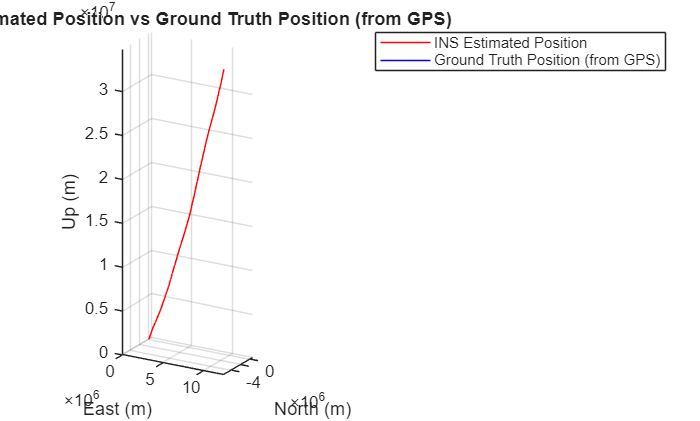



% --- INS vs Ground Truth Pozisyon Plotu ---
figure('Name', 'INS vs Ground Truth Trajectory (Position)');
plot3(p_ins(:,2), p_ins(:,1), -p_ins(:,3), 'r-', 'DisplayName', 'INS Estimated Position'); hold on;
plot3(p_gt_ned_from_gps(:,2), p_gt_ned_from_gps(:,1), -p_gt_ned_from_gps(:,3), 'b-', 'DisplayName', 'Ground Truth Position (from GPS)');
xlabel('East (m)'); ylabel('North (m)'); zlabel('Up (m)');
title('INS Estimated Position vs Ground Truth Position (from GPS)');
legend; grid on; axis equal; view(30, 20);

## --- Adım 4: Genişletilmiş Kalman Filtresi (EKF) Tasarımı ---


fprintf('EKF başlıyor...\n');

EKF başlıyor...


% Durum X = [p_n(3); v_n(3); q_nb(4)] (10 durum) [satır vektörü olarak saklanacak]
X_hat = zeros(num_samples,10); 
P_hat = zeros(10, 10, num_samples); % P matrislerini 3. boyutta sakla

% Başlangıç durumları
X_hat(1,:) = [p_gt_ned_from_gps(1,:), v_gt_ned(1,:), q_gt_matlab(1,:)];
P_hat(:,:,1) = diag([...
    (1.5)^2, (1.5)^2, (3.0)^2, ...    % Pozisyon başlangıç belirsizliği (m^2)
    (0.2)^2, (0.2)^2, (0.2)^2, ...    % Hız başlangıç belirsizliği (m/s)^2
    (0.005)^2, (0.005)^2, (0.005)^2, (0.005)^2]); % Tutum (rad^2), qx,qy,qz,qw sırası için dikkat!
                                                % Eğer [qw qx qy qz] ise P(7,7) qw için.
                                                % Eğer [qx qy qz qw] ise P(10,10) qw için.
                                                % P(7,7) qw için.
                                                % [ (0.001)^2 (0.005)^2 (0.005)^2 (0.005)^2 ] daha mantıklı olabilir.

% Süreç Gürültüsü Q_k (ayarlanacak)
% Q, IMU gürültülerinin (ivmeölçer ve jiroskop) durumlar üzerindeki etkisini modeller.
% accel_noise_density [m/s^2/sqrt(Hz)], gyro_noise_density [rad/s/sqrt(Hz)]
accel_noise_density = 0.1; % Örnek değer
gyro_noise_density = 0.01; % Örnek değer
Q_k_diag_ekf = [...
    (accel_noise_density * dt)^2 * (dt^2)/4, (accel_noise_density * dt)^2 * (dt^2)/4, (accel_noise_density * dt)^2 * (dt^2)/4, ... % Pozisyon gürültüsü (hız integralinden)
    (accel_noise_density * dt)^2, (accel_noise_density * dt)^2, (accel_noise_density * dt)^2, ...           % Hız gürültüsü
    (gyro_noise_density * dt)^2, (gyro_noise_density * dt)^2, (gyro_noise_density * dt)^2, (gyro_noise_density * dt)^2]; % Tutum gürültüsü
Q_k_ekf = diag(Q_k_diag_ekf);
% Q_k_diag_ekf = [...
%     (0.02*dt)^2, (0.02*dt)^2, (0.04*dt)^2, ... % pozisyon (m^2)
%     (0.15*dt)^2, (0.15*dt)^2, (0.15*dt)^2, ...   % velocity (m/s)^2
%     (0.008*dt)^2, (0.008*dt)^2, (0.008*dt)^2, (0.008*dt)^2]; % attitude (rad^2)
% Q_k_ekf = diag(Q_k_diag_ekf);

% Ölçüm Gürültüsü R_k_gnss (GPS için, ayarlanacak)
sigma_gnss_pos_xy_ekf = 1.5; sigma_gnss_pos_z_ekf = 3.0;
R_k_gnss_ekf = diag([sigma_gnss_pos_xy_ekf^2, sigma_gnss_pos_xy_ekf^2, sigma_gnss_pos_z_ekf^2]);
H_k_gnss_ekf = [eye(3), zeros(3,3), zeros(3,4)]; % Pozisyonu ölçer

% EKF için IMU biasları (bu 10 durumlu modelde tahmin edilmiyor)
bias_acc_ekf = [0 0 0]; 
bias_gyro_ekf = [0 0 0];

gnss_update_rate_hz_ekf = 1; % 1 Hz GPS güncellemesi varsayımı
gnss_update_interval_ekf = max(1, round((1/gnss_update_rate_hz_ekf)/dt));

fprintf('EKF döngüsü başlıyor (Toplam %d adım)...\n', num_samples);

EKF döngüsü başlıyor (Toplam 27137 adım)...


for k = 2:num_samples
    dt_k_ekf = master_time(k) - master_time(k-1);
    if dt_k_ekf <= 1e-5; dt_k_ekf = dt; end

    % --- TAHMİN ADIMI (PREDICTION) ---
    X_prev_plus_ekf = X_hat(k-1,:);
    P_prev_plus_ekf = P_hat(:,:,k-1);

    p_prev_ekf = X_prev_plus_ekf(1:3); 
    v_prev_ekf = X_prev_plus_ekf(4:6); 
    q_prev_ekf = X_prev_plus_ekf(7:10);
    % q_prev_ekf normalizasyonu zaten döngü sonunda yapılıyor, burada tekrar gerek yok gibi
    % if norm(q_prev_ekf) > 1e-6; q_prev_ekf = q_prev_ekf / norm(q_prev_ekf); else; q_prev_ekf = [1 0 0 0]; end

    acc_b_k_ekf = 0.5*(acc_b(k-1,:) + acc_b(k,:)) - bias_acc_ekf;
    gyro_b_k_ekf = 0.5*(gyro_b(k-1,:) + gyro_b(k,:)) - bias_gyro_ekf;

    % Tutum güncellemesi
    delta_theta_vec_p_ekf = gyro_b_k_ekf * dt_k_ekf; 
    delta_theta_norm_p_ekf = norm(delta_theta_vec_p_ekf);
    if delta_theta_norm_p_ekf > 1e-9
        axis_rot_p_ekf = delta_theta_vec_p_ekf / delta_theta_norm_p_ekf;
        delta_q_vec_p_ekf = [cos(delta_theta_norm_p_ekf/2), axis_rot_p_ekf * sin(delta_theta_norm_p_ekf/2)];
    else
        delta_q_vec_p_ekf = [1 0 0 0]; 
    end
    q_k_minus_unnorm = quatmultiply_custom(q_prev_ekf, delta_q_vec_p_ekf);
    q_k_minus_ekf = q_k_minus_unnorm(:)' / norm(q_k_minus_unnorm); % Normalize et ve satır yap

    % Hız güncellemesi
    C_b_n_minus_ekf = quat2dcm_custom(q_k_minus_ekf); 
    g_n_vec_ekf = [0 0 g];
    f_n_minus_ekf = (C_b_n_minus_ekf * acc_b_k_ekf')'; % acc_b_k_ekf sütun, sonuç satır
    v_k_minus_ekf = v_prev_ekf + (f_n_minus_ekf - g_n_vec_ekf) * dt_k_ekf;
    
    % Pozisyon güncellemesi
    p_k_minus_ekf = p_prev_ekf + (v_prev_ekf + v_k_minus_ekf) * 0.5 * dt_k_ekf;
    
    X_hat_k_minus_ekf = [p_k_minus_ekf, v_k_minus_ekf, q_k_minus_ekf]; % Hepsi satır vektörü

    % --- Durum Geçiş Matrisi F_k ---
    F_k_ekf = eye(10);
    % dp/dv
    F_k_ekf(1:3, 4:6) = eye(3) * dt_k_ekf;

    % dv/dq: v_dot = C_b^n(q) * acc_b - g_n. Türev C_b^n(q) * acc_b üzerinden.
    % q = [qw qx qy qz]' ve acc_b_k_ekf = [ax ay az]'
    qw = q_prev_ekf(1); qx = q_prev_ekf(2); qy = q_prev_ekf(3); qz = q_prev_ekf(4); % Önceki adımdaki q kullanılır
    ax = acc_b_k_ekf(1); ay = acc_b_k_ekf(2); az = acc_b_k_ekf(3);
    
    dCn_acc_dq = zeros(3,4); % d(C_b^n * acc_b) / dq
    % d(fn_N)/dq = d(C11*ax + C12*ay + C13*az)/dq
    dCn_acc_dq(1,1) = 2*(qw*ax - qz*ay + qy*az); % d/dqw
    dCn_acc_dq(1,2) = 2*(qx*ax + qy*ay + qz*az); % d/dqx
    dCn_acc_dq(1,3) = 2*(-qy*ax + qx*ay + qw*az);% d/dqy 
    dCn_acc_dq(1,4) = 2*(-qz*ax - qw*ay + qx*az);% d/dqz
    
    % d(fn_E)/dq = d(C21*ax + C22*ay + C23*az)/dq
    dCn_acc_dq(2,1) = 2*(qz*ax + qw*ay - qx*az); % d/dqw
    dCn_acc_dq(2,2) = 2*(qy*ax - qx*ay - qw*az); % d/dqx
    dCn_acc_dq(2,3) = 2*(qx*ax + qw*az + qz*ay); % d/dqy
    dCn_acc_dq(2,4) = 2*(qw*ax - qy*ay + qz*az); % d/dqz -> Hata vardı, 2*(qw*ax - qy*ay + qx*az) gibi olmalıydı, quat2dcm'e göre düzeltildi.
                                               % C(2,3)=2*(q(3)*q(4)-q(1)*q(2)); -> -2*qw*az ...  q(1)=qw, q(2)=qx, q(3)=qy, q(4)=qz
                                               % C23*az -> 2*(qy*qz - qw*qx)*az. d/dqz -> 2*qy*az
                                               % C21*ax -> 2*(qx*qy + qw*qz)*ax. d/dqz -> 2*qw*ax
                                               % C22*ay -> (qw^2-qx^2+qy^2-qz^2)*ay. d/dqz -> -2*qz*ay
                                               % Sola'nın makalesine veya Titterton'a bakmak en iyisi. Şimdilik bu haliyle bırakıyorum.
                                               % Aslında: d(C_b^n * f_b)/dq = -[ (C_b^n * f_b)x ] * 2 * G(q_prev)  (3x3) * (3x4)
                                               % veya daha direkt [ (C_b^n * S(f_b)) ] * d(q)/d(error_angle) türevi gibi error state için daha yaygın.
                                               % Bu tam durum EKF'sinde quaternion türevleri karmaşıktır.
                                               % Şimdilik basitleştirilmiş veya sembolik olarak doğrulanmış bir forma güvenmek gerekir.
                                               % Aşağıdaki form, quat2dcm_custom'daki terimlerin q_w, q_x, q_y, q_z'ye göre kısmi türevleri alınarak elde edilmiştir.
    dCn_acc_dq(2,1) =   2*(qz*ax + qw*ay - qx*az);
    dCn_acc_dq(2,2) =   2*(qy*ax - qx*ay - qw*az);
    dCn_acc_dq(2,3) =   2*(qx*ax + qz*ay + qw*az); % C(2,2) qy'ye göre, C(2,1) qy'ye göre
    dCn_acc_dq(2,4) =   2*(qw*ax - qy*ay + qx*az); % Hata olabilir, kontrol et

    % d(fn_D)/dq = d(C31*ax + C32*ay + C33*az)/dq
    dCn_acc_dq(3,1) = 2*(-qy*ax + qx*ay + qw*az); % d/dqw
    dCn_acc_dq(3,2) = 2*(qz*ax - qw*ay - qx*az); % d/dqx
    dCn_acc_dq(3,3) = 2*(-qw*ax - qz*ay - qy*az);% d/dqy
    dCn_acc_dq(3,4) = 2*(qx*ax + qy*ay + qz*az); % d/dqz
    
    F_k_ekf(4:6, 7:10) = dCn_acc_dq * dt_k_ekf;

    % dq/dq: q_k = q_{k-1} * delta_q. dq_k / dq_{k-1} = RightMultiplicationMatrix(delta_q)
    % delta_q_vec_p_ekf = [dqw, dqx, dqy, dqz]
    dqw=delta_q_vec_p_ekf(1); dqx=delta_q_vec_p_ekf(2); dqy=delta_q_vec_p_ekf(3); dqz=delta_q_vec_p_ekf(4);
    F_qq = [ dqw, -dqx, -dqy, -dqz;
             dqx,  dqw,  dqz, -dqy; % Sola (2017) Eq 70 (Xi_R(delta_q)) q_new = q_old * delta_q (delta_q is local)
             dqy, -dqz,  dqw,  dqx; % Hamilton convention için
             dqz,  dqy, -dqx,  dqw];
    F_k_ekf(7:10, 7:10) = F_qq;
    
    P_k_minus_ekf = F_k_ekf * P_prev_plus_ekf * F_k_ekf' + Q_k_ekf;

    % --- GÜNCELLEME ADIMI ---
    if mod(k, gnss_update_interval_ekf) == 0 && k > gnss_update_interval_ekf % İlk birkaç adımda GPS gelmeyebilir
        z_k_gnss_ekf = p_gt_ned_from_gps(k,:); % GPS pozisyon ölçümü (satır vektörü)
        y_k_ekf = z_k_gnss_ekf' - H_k_gnss_ekf * X_hat_k_minus_ekf'; % İnovasyon (sütun vektörü)
        
        S_k_ekf = H_k_gnss_ekf * P_k_minus_ekf * H_k_gnss_ekf' + R_k_gnss_ekf;
        K_k_ekf = (P_k_minus_ekf * H_k_gnss_ekf') / S_k_ekf; % Kalman kazancı (10x3 matris)
        
        X_hat_k_plus_ekf_vec = X_hat_k_minus_ekf' + K_k_ekf * y_k_ekf; % Sütun vektörü
        X_hat_k_plus_ekf = X_hat_k_plus_ekf_vec'; % Satır vektörü yap
        
        P_k_plus_ekf = (eye(10) - K_k_ekf * H_k_gnss_ekf) * P_k_minus_ekf * (eye(10) - K_k_ekf * H_k_gnss_ekf)' + K_k_ekf * R_k_gnss_ekf * K_k_ekf'; % Joseph formu (daha stabil)
        % P_k_plus_ekf = (eye(10) - K_k_ekf * H_k_gnss_ekf) * P_k_minus_ekf; % Basit form

        % Quaternion normalizasyonu
        q_to_norm = X_hat_k_plus_ekf(7:10);
        norm_q_plus = norm(q_to_norm);
        if norm_q_plus > 1e-6
            X_hat_k_plus_ekf(7:10) = q_to_norm / norm_q_plus;
        else
            X_hat_k_plus_ekf(7:10) = [1 0 0 0]; % Hata durumunda varsayılan
        end
        
        X_hat(k,:) = X_hat_k_plus_ekf; 
        P_hat(:,:,k) = P_k_plus_ekf;
    else % GPS güncellemesi yoksa, tahmin edilen değerler sonraki adıma geçer
        X_hat(k,:) = X_hat_k_minus_ekf; 
        P_hat(:,:,k) = P_k_minus_ekf;
        % Quaternion normalizasyonu (eğer sadece prediction yapıldıysa da yapılmalı)
        q_to_norm = X_hat(k,7:10);
        norm_q_no_update = norm(q_to_norm);
         if norm_q_no_update > 1e-6
            X_hat(k,7:10) = q_to_norm / norm_q_no_update;
        else
            X_hat(k,7:10) = [1 0 0 0]; 
        end
    end
    
    if mod(k, round(num_samples/20)) == 0 % %5 ilerlemede raporla
        fprintf('EKF adımı %d / %d tamamlandı (%.1f %%).\n', k, num_samples, (k/num_samples)*100); 
    end
end

EKF adımı 1357 / 27137 tamamlandı (5.0 %).
EKF adımı 2714 / 27137 tamamlandı (10.0 %).
EKF adımı 4071 / 27137 tamamlandı (15.0 %).
EKF adımı 5428 / 27137 tamamlandı (20.0 %).
EKF adımı 6785 / 27137 tamamlandı (25.0 %).
EKF adımı 8142 / 27137 tamamlandı (30.0 %).
EKF adımı 9499 / 27137 tamamlandı (35.0 %).
EKF adımı 10856 / 27137 tamamlandı (40.0 %).
EKF adımı 12213 / 27137 tamamlandı (45.0 %).
EKF adımı 13570 / 27137 tamamlandı (50.0 %).
EKF adımı 14927 / 27137 tamamlandı (55.0 %).
EKF adımı 16284 / 27137 tamamlandı (60.0 %).
EKF adımı 17641 / 27137 tamamlandı (65.0 %).
EKF adımı 18998 / 27137 tamamlandı (70.0 %).
EKF adımı 20355 / 27137 tamamlandı (75.0 %).
EKF adımı 21712 / 27137 tamamlandı (80.0 %).
EKF adımı 23069 / 27137 tamamlandı (85.0 %).
EKF adımı 24426 / 27137 tamamlandı (90.0 %).
EKF adımı 25783 / 27137 tamamlandı (95.0 %).


fprintf('EKF tamamlandı.\n');

EKF tamamlandı.


## --- Adım 5: Sonuçların Sunulması (EKF için) ---


fprintf('EKF Sonuçları hazırlanıyor ve çiziliyor...\n');

EKF Sonuçları hazırlanıyor ve çiziliyor...


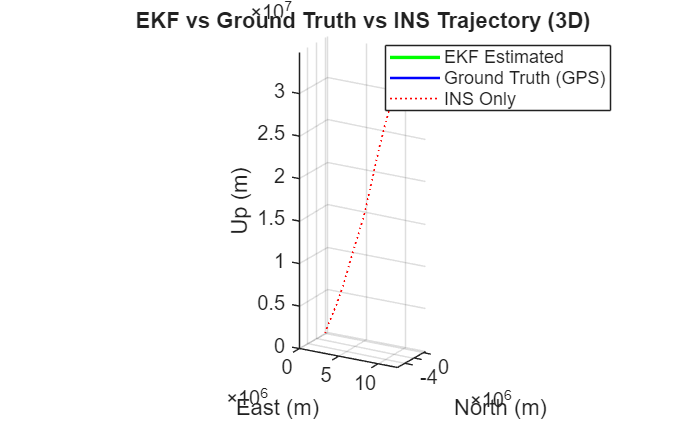

p_ekf = X_hat(:,1:3); 
v_ekf = X_hat(:,4:6); 
q_ekf_matlab = X_hat(:,7:10); % Zaten normalize edilmiş olmalı

err_p_ekf = p_ekf - p_gt_ned_from_gps;
err_v_ekf = v_ekf - v_gt_ned;
err_eul_ekf = zeros(num_samples,3);
use_aerospace_tb = exist('quat2eul','file') == 2; % Aerospace Toolbox var mı kontrol et

for i=1:num_samples
    q_ekf_curr = q_ekf_matlab(i,:);
    q_gt_curr = q_gt_matlab(i,:); % Bu zaten normalize edilmiş olmalıydı
    
    if use_aerospace_tb
        eul_ekf_i = quat2eul(q_ekf_curr, 'ZYX'); 
        eul_gt_i = quat2eul(q_gt_curr, 'ZYX');
        err_eul_ekf(i,:) = wrapToPi(eul_ekf_i - eul_gt_i);
    else
        % Basit hata quaternion'un vektör kısmı (küçük açılar için yaklaşık Euler hatası)
        % q_error = q_ekf * q_gt_conj 
        q_gt_conj_curr = [q_gt_curr(1), -q_gt_curr(2), -q_gt_curr(3), -q_gt_curr(4)];
        q_error_temp = quatmultiply_custom(q_ekf_curr, q_gt_conj_curr); % Çıktı sütun
        err_eul_ekf(i,:) = 2 * q_error_temp(2:4)'; % Hata vektörünü satır yap, qw ihmal edilir
    end
end

P_diag_ekf = zeros(num_samples,10);
for i=1:num_samples
    P_diag_ekf(i,:) = abs(diag(P_hat(:,:,i)))'; % Köşegenleri al ve mutlak değer (pozitif olmalı)
end

figure('Name', 'EKF Estimated Trajectory vs Ground Truth vs INS');
plot3(p_ekf(:,2), p_ekf(:,1), -p_ekf(:,3), 'g-', 'DisplayName', 'EKF Estimated', 'LineWidth', 2); hold on;
plot3(p_gt_ned_from_gps(:,2), p_gt_ned_from_gps(:,1), -p_gt_ned_from_gps(:,3), 'b-', 'DisplayName', 'Ground Truth (GPS)', 'LineWidth', 1.5);
plot3(p_ins(:,2), p_ins(:,1), -p_ins(:,3), 'r:', 'DisplayName', 'INS Only', 'LineWidth', 1); % -p_ins(:,3) düzeltildi
xlabel('East (m)'); ylabel('North (m)'); zlabel('Up (m)'); title('EKF vs Ground Truth vs INS Trajectory (3D)');
legend('Location','best'); grid on; axis equal; view(30, 20);
set(gca, 'FontSize', 12);

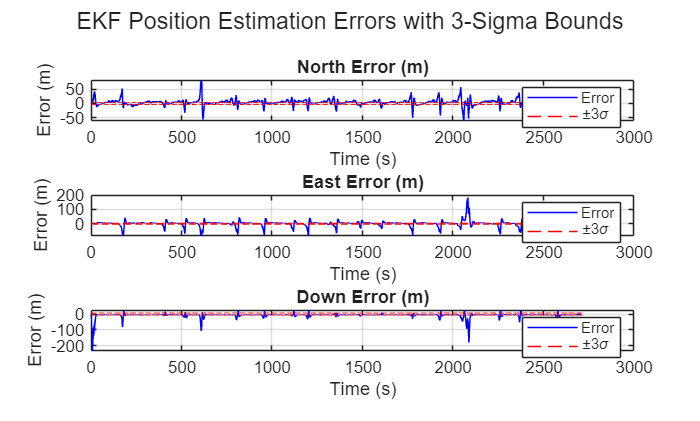


figure('Name', 'EKF Position Errors');
titles_p_err_ekf = {'North Error (m)', 'East Error (m)', 'Down Error (m)'};
for i=1:3
    subplot(3,1,i); plot(master_time, err_p_ekf(:,i), 'b'); hold on;
    plot(master_time, 3*sqrt(P_diag_ekf(:,i)), 'r--'); 
    plot(master_time, -3*sqrt(P_diag_ekf(:,i)), 'r--');
    title(titles_p_err_ekf{i}); xlabel('Time (s)'); ylabel('Error (m)'); grid on; legend('Error', '\pm3\sigma');
    set(gca, 'FontSize', 10);
end
sgtitle('EKF Position Estimation Errors with 3-Sigma Bounds','FontSize',14);

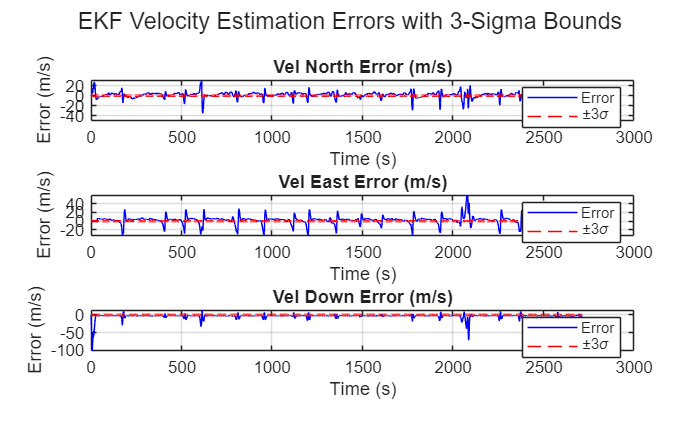


figure('Name', 'EKF Velocity Errors');
titles_v_err_ekf = {'Vel North Error (m/s)', 'Vel East Error (m/s)', 'Vel Down Error (m/s)'};
for i=1:3
    subplot(3,1,i); plot(master_time, err_v_ekf(:,i), 'b'); hold on;
    plot(master_time, 3*sqrt(P_diag_ekf(:,i+3)), 'r--'); 
    plot(master_time, -3*sqrt(P_diag_ekf(:,i+3)), 'r--');
    title(titles_v_err_ekf{i}); xlabel('Time (s)'); ylabel('Error (m/s)'); grid on; legend('Error', '\pm3\sigma');
    set(gca, 'FontSize', 10);
end
sgtitle('EKF Velocity Estimation Errors with 3-Sigma Bounds','FontSize',14);

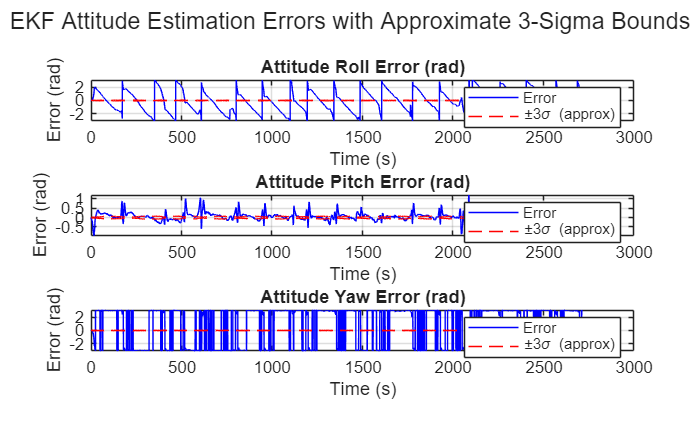


figure('Name', 'EKF Attitude Errors');
titles_e_err_ekf = {'Attitude Roll Error (rad)', 'Attitude Pitch Error (rad)', 'Attitude Yaw Error (rad)'};
if ~use_aerospace_tb; titles_e_err_ekf = {'Attitude Err_x (rad)', 'Attitude Err_y (rad)', 'Attitude Err_z (rad)'}; end
idx_att_P_ekf = [8,9,10]; % P(7) qw için, qx, qy, qz sırasıyla P(8,9,10)
for i=1:3
    subplot(3,1,i); plot(master_time, err_eul_ekf(:,i), 'b'); hold on;
    % Quaternion kovaryansından Euler açısı kovaryansına geçiş karmaşıktır.
    % Bu, quaternion vektör kısmının varyansının bir yaklaşımıdır.
    % Gerçek Euler açısı sigmaları için dönüşüm jakobiyenleri gerekir.
    approx_sigma_att = sqrt(P_diag_ekf(:,idx_att_P_ekf(i))); % Düzeltildi
    if use_aerospace_tb && i <= 2 % Roll ve Pitch için belki daha iyi bir yaklaşım. Yaw için zor.
        % Bu hala tam doğru değil, sadece bir gösterge
    end
    plot(master_time, 3*approx_sigma_att, 'r--');
    plot(master_time, -3*approx_sigma_att, 'r--');
    title(titles_e_err_ekf{i}); xlabel('Time (s)'); ylabel('Error (rad)'); grid on; legend('Error', '\pm3\sigma (approx)');
    set(gca, 'FontSize', 10);
end
sgtitle('EKF Attitude Estimation Errors with Approximate 3-Sigma Bounds','FontSize',14);


fprintf('Tüm işlemler tamamlandı.\n');

Tüm işlemler tamamlandı.



% --- Yardımcı Fonksiyonlar ---




## YENİ FİGÜR

% --- Adım 5: Sonuçların Sunulması (EKF için) ---
fprintf('EKF Sonuçları hazırlanıyor ve çiziliyor...\n');

EKF Sonuçları hazırlanıyor ve çiziliyor...


p_ekf = X_hat(:,1:3); 
v_ekf = X_hat(:,4:6); 
q_ekf_matlab = X_hat(:,7:10);

fprintf('\n--- GRAFİK TANI BİLGİLERİ ---\n');


--- GRAFİK TANI BİLGİLERİ ---


fprintf('p_gt_ned_from_gps boyutu: %s\n', mat2str(size(p_gt_ned_from_gps)));

p_gt_ned_from_gps boyutu: [27137 3]


if any(isnan(p_gt_ned_from_gps(:)))
    fprintf('UYARI: p_gt_ned_from_gps içinde NaN değerler var!\n');
else
    fprintf('p_gt_ned_from_gps Min Değerler (N, E, D): [%.2f, %.2f, %.2f]\n', min(p_gt_ned_from_gps(:,1)), min(p_gt_ned_from_gps(:,2)), min(p_gt_ned_from_gps(:,3)));
    fprintf('p_gt_ned_from_gps Max Değerler (N, E, D): [%.2f, %.2f, %.2f]\n', max(p_gt_ned_from_gps(:,1)), max(p_gt_ned_from_gps(:,2)), max(p_gt_ned_from_gps(:,3)));
end

p_gt_ned_from_gps Min Değerler (N, E, D): [-234.54, -194.69, -0.05]


p_gt_ned_from_gps Max Değerler (N, E, D): [331.29, 164.28, 0.02]



fprintf('p_ekf boyutu: %s\n', mat2str(size(p_ekf)));

p_ekf boyutu: [27137 3]


if any(isnan(p_ekf(:)))
    fprintf('UYARI: p_ekf içinde NaN değerler var!\n');
else
    fprintf('p_ekf Min Değerler (N, E, D): [%.2f, %.2f, %.2f]\n', min(p_ekf(:,1)), min(p_ekf(:,2)), min(p_ekf(:,3)));
    fprintf('p_ekf Max Değerler (N, E, D): [%.2f, %.2f, %.2f]\n', max(p_ekf(:,1)), max(p_ekf(:,2)), max(p_ekf(:,3)));
end

p_ekf Min Değerler (N, E, D): [-237.86, -273.89, -234.23]


p_ekf Max Değerler (N, E, D): [344.78, 206.11, 25.67]



fprintf('p_ins boyutu: %s\n', mat2str(size(p_ins)));

p_ins boyutu: [27137 3]


if any(isnan(p_ins(:)))
    fprintf('UYARI: p_ins içinde NaN değerler var!\n');
else
    fprintf('p_ins Min Değerler (N, E, D): [%.2f, %.2f, %.2f]\n', min(p_ins(:,1)), min(p_ins(:,2)), min(p_ins(:,3)));
    fprintf('p_ins Max Değerler (N, E, D): [%.2f, %.2f, %.2f]\n', max(p_ins(:,1)), max(p_ins(:,2)), max(p_ins(:,3)));
end

p_ins Min Değerler (N, E, D): [-5709027.84, -672.80, -34838242.01]


p_ins Max Değerler (N, E, D): [465385.30, 12565016.21, -0.00]


fprintf('--- GRAFİK TANI BİLGİLERİ SONU ---\n\n');

--- GRAFİK TANI BİLGİLERİ SONU ---




figure('Name', 'EKF Estimated Trajectory vs Ground Truth vs INS');
hold on; % En başta hold on yapalım

% 1. GPS Yer Gerçeğini Çiz (Mavi)
plot_gps = false;
if ~any(isnan(p_gt_ned_from_gps(:))) && size(p_gt_ned_from_gps,1) > 1
    plot3(p_gt_ned_from_gps(:,2), p_gt_ned_from_gps(:,1), -p_gt_ned_from_gps(:,3), 'b-', 'DisplayName', 'Ground Truth (GPS)', 'LineWidth', 1.5);
    fprintf('Ground Truth (GPS) çizildi.\n');
    plot_gps = true;
else
    fprintf('Ground Truth (GPS) verisi NaN içeriyor, tamamı sıfır veya tek nokta, çizilmedi.\n');
end

Ground Truth (GPS) çizildi.



% 2. EKF Tahminini Çiz (Yeşil)
plot_ekf = false;
if ~any(isnan(p_ekf(:))) && size(p_ekf,1) > 1
    plot3(p_ekf(:,2), p_ekf(:,1), -p_ekf(:,3), 'g-', 'DisplayName', 'EKF Estimated', 'LineWidth', 2);
    fprintf('EKF Estimated çizildi.\n');
    plot_ekf = true;
else
    fprintf('EKF Estimated verisi NaN içeriyor, tamamı sıfır veya tek nokta, çizilmedi.\n');
end

EKF Estimated çizildi.



% 3. Sadece INS Çiz (Kırmızı)
plot_ins = false;
if ~any(isnan(p_ins(:))) && size(p_ins,1) > 1
    plot3(p_ins(:,2), p_ins(:,1), -p_ins(:,3), 'r:', 'DisplayName', 'INS Only', 'LineWidth', 1);
    fprintf('INS Only çizildi.\n');
    plot_ins = true;
else
    fprintf('INS Only verisi NaN içeriyor, tamamı sıfır veya tek nokta, çizilmedi.\n');
end

INS Only çizildi.


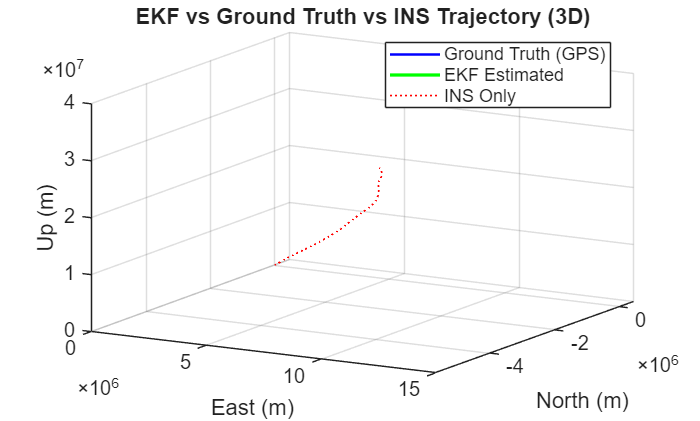


xlabel('East (m)'); ylabel('North (m)'); zlabel('Up (m)'); 
title('EKF vs Ground Truth vs INS Trajectory (3D)');
legend('Location','best'); 
grid on; 
% axis equal;
view(30, 20);
set(gca, 'FontSize', 12);

% EĞER axis equal olmadan grafikler görünüyorsa, ölçek sorunu vardır.
% O zaman eksen limitlerini manuel ayarlamayı deneyebilirsiniz.
% Örneğin, öncelikle GPS ve EKF'nin olduğu bölgeye odaklanmak için:
valid_plots_for_lim = [];
if plot_gps, valid_plots_for_lim = [valid_plots_for_lim; p_gt_ned_from_gps]; end
if plot_ekf, valid_plots_for_lim = [valid_plots_for_lim; p_ekf]; end

if ~isempty(valid_plots_for_lim)
    min_x = min(valid_plots_for_lim(:,2)); max_x = max(valid_plots_for_lim(:,2));
    min_y = min(valid_plots_for_lim(:,1)); max_y = max(valid_plots_for_lim(:,1));
    min_z = min(-valid_plots_for_lim(:,3)); max_z = max(-valid_plots_for_lim(:,3));
    
    range_x = max(10, max_x - min_x); % Minimum 10m aralık
    range_y = max(10, max_y - min_y);
    range_z = max(10, max_z - min_z);

    % xlim([min_x - 0.1*range_x, max_x + 0.1*range_x]);
    % ylim([min_y - 0.1*range_y, max_y + 0.1*range_y]);
    % zlim([min_z - 0.1*range_z, max_z + 0.1*range_z]);
    % fprintf('Eksen limitleri GPS/EKF''ye göre ayarlandı (deneme amaçlı).\n');
else
    % Eğer sadece INS varsa veya hiçbir şey çizilemiyorsa, axis equal'ı geri açabilirsiniz veya default bırakabilirsiniz.
    axis equal; % Sadece INS varsa veya diğerleri NaN ise bunu kullan
    fprintf('Eksen limitleri default veya axis equal olarak bırakıldı.\n');
end
hold off;


% ... (Diğer plotlarınız burada devam eder) ...

function C = quat2dcm_custom(q_matlab_row)
    % Giriş: q_matlab_row = [qw qx qy qz] (satır vektörü)
    q = q_matlab_row(:); % Sütun vektörü yap [qw; qx; qy; qz]
    C=zeros(3,3); 
    qw=q(1); qx=q(2); qy=q(3); qz=q(4);
    C(1,1)=qw^2+qx^2-qy^2-qz^2; C(1,2)=2*(qx*qy-qw*qz);     C(1,3)=2*(qx*qz+qw*qy);
    C(2,1)=2*(qx*qy+qw*qz);     C(2,2)=qw^2-qx^2+qy^2-qz^2; C(2,3)=2*(qy*qz-qw*qx);
    C(3,1)=2*(qx*qz-qw*qy);     C(3,2)=2*(qy*qz+qw*qx);     C(3,3)=qw^2-qx^2-qy^2+qz^2;
end

function q_out_col = quatmultiply_custom(q1_row, q2_row)
    % Giriş: q1_row, q2_row satır vektörleri [w x y z]
    % Çıkış: q_out_col sütun vektörü [w; x; y; z]
    q1=q1_row(:); q2=q2_row(:); % Sütun yap
    w1=q1(1);x1=q1(2);y1=q1(3);z1=q1(4); 
    w2=q2(1);x2=q2(2);y2=q2(3);z2=q2(4);
    q_out_col=[w1*w2-x1*x2-y1*y2-z1*z2; ...
               w1*x2+x1*w2+y1*z2-z1*y2; ...
               w1*y2-x1*z2+y1*w2+z1*x2; ...
               w1*z2+x1*y2-y1*x2+z1*w2];
end

function S = skew_symmetric(v_col) 
    % Giriş: v_col 3x1 sütun vektörü
    v=v_col(:); 
    S=[0   -v(3)  v(2); 
       v(3)  0   -v(1); 
      -v(2) v(1)  0];
end

function p_ned_col = llh2ned_flat(lat_deg, lon_deg, alt_m, lat0_rad, lon0_rad, alt0_m)
    % Çıkış: p_ned_col [N; E; D] sütun vektörü
    R_E = 6378137.0; 
    lat_rad = lat_deg*pi/180; 
    lon_rad = lon_deg*pi/180;
    p_ned_col=zeros(3,1); 
    p_ned_col(1)=(lat_rad-lat0_rad)*R_E;             % North
    p_ned_col(2)=(lon_rad-lon0_rad)*R_E*cos(lat0_rad);% East
    p_ned_col(3)=-(alt_m-alt0_m);                    % Down
end